# Leitor de arquivo no formato CRFS BIN.

Trata-se de leitor dos principais tipos de dados relacionados às versões 3, 4 e 5 de arquivo no formato CRFS BIN, gerado originalmente pela aplicação Logger, do RFeye. Além do Logger, cujo uso se restringe aos receptores RFeye, é possível gerar arquivo no formato CRFS BIN usando a aplicação 3A Spectrum, em desenvolvimento na Gerência Regional nos Estados da Bahia e Sergipe, a qual possibilita captura de dados espectrais por meio de alguns dos analisadores de espectro e receptores que a Agência dispõe.

Em relação ao *script* carregado no Logger, recomenda-se inclusão do número de *sweeps* para o cômputo das operações **peak,** **mean e occ** no campo descrição, como indicado a seguir: peak = 10, ab, 10 scan, **"trace mode: MaxHold, count = 10"**, cont=1

Versão: **10/12/2020**

function [SpecInfo, Samples] = Fcn_BinFileReaderV3(filename, ReadType, metaData)

    arguments
        filename char
        ReadType char
        metaData struct
    end
    
    global FileVersion
    
    global SpecInfo
    global Samples
    
    global CheckSumAdd
    global CheckSum_NRB
    global CheckSum_NEB
    global CheckSum_RXE
    
    CheckSumAdd    = [];
    CheckSum_NRB   = 0;           % Número de blocos de dados que NÃO contém erro. Análise do CheckSum e EOFMarker.
    CheckSum_NEB   = 0;           % Número de blocos de dados que contém erro. Análise do CheckSum e EOFMarker.
    CheckSum_RXE   = 0;           % Número de blocos de dados relacionados a erros no receptor ou no processamento (GERROR)
    
%     tic
    fileID = fopen(filename);
    if fileID == -1
        error('Error Code 1: Invalid path or file name.');
    end
    
    FH_Format  = fread(fileID, 1, 'int32', 32);                 % 21 (File version: 3), 22 (File version: 4) e 23 (File version: 5)
    switch FH_Format
        case 21; FileVersion = 'CRFS BIN v.3';
        case 22; FileVersion = 'CRFS BIN v.4';
        case 23; FileVersion = 'CRFS BIN v.5';
    end
%     FH_sFormat = deblank(fread(fileID, [1, 32], '*char'));  % 'CRFS DATA FILE V023             '
%     if ~contains(FH_sFormat, 'CRFS')
%         error('Error Code 2: Appears not to be a CRFS binary file.');
%     end
    
    switch ReadType
        case {'MetaData', 'SingleFile'}
            SpecInfo = struct('Node', [], 'ThreadID', [], 'General', [], 'Resolution', [], 'Threshold', [], 'TraceMode', [], 'Detector', [], ...
                              'Samples', [], 'Data', [], 'statsData', [], 'FileVersion', [], 'DataType', [], 'ScriptName', [], ...
                              'Description', [], 'AntennaID', [], 'gpsString', [], 'gpsFlag', [], 'occRelated', [], 'occFlag', []);
            
            Fcn_MetaDataReader(fileID);
            
            if strcmp(ReadType, 'SingleFile')
                Fcn_SpecDataReader(fileID)
            end
            
        case 'SpecData'
            SpecInfo = metaData(1).Data;
            Samples  = metaData(1).Samples;
            
            Fcn_SpecDataReader(fileID);
    end
%     t1 = toc;
%     fprintf('Elapsed time (file read): %f seconds\n', t1);

%     fprintf(['File: %s\nSummary of the reading process:\n' ...
%             '- Elapsed time (file read)..: %f seconds \n' ...
%             '- CheckSum/EOFMarker Error..: %d of %d data blocks (%f %%) \n'   ...
%             '- Global Error Code.........: %d spectral data blocks \n\n'], filename, t1, CheckSum_NEB, (CheckSum_NEB+CheckSum_NRB), (CheckSum_NEB/(CheckSum_NEB+CheckSum_NRB)).*100, CheckSum_RXE);
    
    fclose(fileID);
end

Leitura de **metadados**.

function Fcn_MetaDataReader(fileID)

    global FileVersion
    
    global SpecInfo
    global Samples
%     global GPS
    
    Index      = 0;
    auxStrCell = {};
    Samples    = 0;
    GPS        = struct('Status',     0, ...
                        'Satellites', 0, ...
                        'Heading',    0, ...
                        'Latitude',   0, ...
                        'Longitude',  0, ...
                        'Speed',      0, ...
                        'Altitude',   0);
    gpsSamples = 0;    
    
    ii = 0;
    while ~feof(fileID)
        DBH_ThreadID   = fread(fileID, 1, 'uint32');
        DBH_BytesBlock = fread(fileID, 1, 'uint32');
        DBH_DataType   = fread(fileID, 1,  'int32');
        
        if ~isempty(DBH_DataType)
            switch DBH_DataType
                case 3
                    Read_DataType3(fileID, DBH_BytesBlock);
                    
                case 21
                    [Hostname, ~, ScriptName, ~] = Read_DataType21(fileID, DBH_BytesBlock);
                    
                case {22, 24}
                    ii = ii+1;
                    if DBH_DataType == 22;     auxStrTraceMode  = Read_DataType22(fileID, DBH_BytesBlock);
                    else                 ; [~, auxStrTraceMode] = Read_DataType24(fileID, DBH_BytesBlock);
                    end
                    auxStrCell(ii, 1:2) = {DBH_ThreadID, auxStrTraceMode};
                    
                case 40
                    [~, auxGPS] = Read_DataType40(fileID, DBH_BytesBlock);
                    
                    gpsSamples = gpsSamples+1;
                    if gpsSamples == 1
                        GPS = auxGPS;
                    else
                        if auxGPS.Status
                            GPS.Latitude  = (99*GPS.Latitude  + auxGPS.Latitude) /100;
                            GPS.Longitude = (99*GPS.Longitude + auxGPS.Longitude)/100;
                            GPS.Altitude  = (99*GPS.Altitude  + auxGPS.Altitude) /100;
                        end
                    end
                    
                case 41
                    Read_DataType41(fileID, DBH_BytesBlock);
                    
                case 42
                    Read_DataType42(fileID, DBH_BytesBlock);
                    
                case {60, 61, 62, 63, 64, 65, 67, 68, 69}
                    auxIndex = find([SpecInfo.ThreadID] == DBH_ThreadID, 1);
                    if isempty(auxIndex)
                        Index = Index+1;
                        
                        switch DBH_DataType
                            case 60; Bin = Read_DataType60(fileID, DBH_BytesBlock, 0);
                            case 61; Bin = Read_DataType61(fileID, DBH_BytesBlock, 0);
                            case 62; Bin = Read_DataType62(fileID, DBH_BytesBlock, 0);
                            case 63; Bin = Read_DataType63(fileID, DBH_BytesBlock, 0);
                            case 64; Bin = Read_DataType64(fileID, DBH_BytesBlock, 0);
                            case 65; Bin = Read_DataType65(fileID, DBH_BytesBlock, 0);
                            case 67; Bin = Read_DataType67(fileID, DBH_BytesBlock, 0);
                            case 68; Bin = Read_DataType68(fileID, DBH_BytesBlock, 0);
                            case 69; Bin = Read_DataType69(fileID, DBH_BytesBlock, 0);
                        end
                        SpecInfo(Index).Node       = Hostname;
                        SpecInfo(Index).ThreadID   = DBH_ThreadID;
                        SpecInfo(Index).General    = [Bin.F0, Bin.F1, Bin.DTYPE, Bin.NDATA];
                        SpecInfo(Index).Resolution = Bin.Resolution;
                        SpecInfo(Index).Threshold  = Bin.THRESH;
                        SpecInfo(Index).TraceMode  = Bin.PROC;
                        SpecInfo(Index).DataType   = DBH_DataType;
                        SpecInfo(Index).AntennaID  = Bin.AntennaID;
                        
                        Samples(Index,1) = 1;
                        
                        if isfield(Bin, 'Text')
                            auxStrCell(Index, 1:2) = {DBH_ThreadID, Bin.Text};
                        end
                    else
                        Samples(auxIndex) = Samples(auxIndex) + 1;
                        Read_CheckSum(fileID, DBH_BytesBlock)
                        fseek(fileID, DBH_BytesBlock, 'cof');
                    end
                    
                otherwise
                    warning(['DataType ' num2str(DBH_DataType) ' function missing!']);
                    Read_CheckSum(fileID, DBH_BytesBlock)
                    fseek(fileID, DBH_BytesBlock, 'cof');
                    
            end
            Read_DataBlockTrailer(fileID, DBH_ThreadID, DBH_DataType);
            
        end
    end
    auxRows = size(auxStrCell, 1);
    
    for jj = auxRows:-1:1
        if ~ismember(auxStrCell{jj,1}, [SpecInfo.ThreadID])
           auxStrCell(jj,:) = [];
        end
    end
    auxStrCell = sortrows(auxStrCell);
    
    [~, auxIndex] = sort([SpecInfo.ThreadID]);
    SpecInfo = SpecInfo(auxIndex);
    Samples  = Samples(auxIndex);
    
    for kk = 1:length(SpecInfo)
        SpecInfo(kk).FileVersion = FileVersion;
        
        SpecInfo(kk).ScriptName  = ScriptName;
        SpecInfo(kk).Description = auxStrCell{kk, 2};
        
        if GPS.Satellites
            SpecInfo(kk).gpsString = [num2str(GPS.Latitude.*1e-6) ', ' num2str(GPS.Longitude.*1e-6) ', ' num2str(GPS.Altitude.*1e-3) 'm'];
            SpecInfo(kk).gpsFlag   = 0;
        else
            SpecInfo(kk).gpsString = '';
            SpecInfo(kk).gpsFlag   = 1;
        end
    end
end

Leitura de informações de **níveis apenas dos dados de blocos espectrais (incluso ocupação)**.

function Fcn_SpecDataReader(fileID)

    global SpecInfo
    global Samples
    global Index
    
    for ii = 1:length(SpecInfo)
        SpecInfo(ii).Samples = 0;
        SpecInfo(ii).Data  = {repmat(datetime(0,0,0),     1, Samples(ii)),       ...
                              zeros(SpecInfo(ii).General(4), Samples(ii), 'single')};
    end
    
    fseek(fileID, 36, 'bof');
    
    while ~feof(fileID)
        DBH_ThreadID   = fread(fileID, 1, 'uint32');
        DBH_BytesBlock = fread(fileID, 1, 'uint32');
        DBH_DataType   = fread(fileID, 1,  'int32');
        
        if ~isempty(DBH_DataType)
            if ismember(DBH_DataType, [60, 61, 62, 63, 64, 65, 67, 68, 69])
                Index = find([SpecInfo.ThreadID] == DBH_ThreadID);
                SpecInfo(Index).Samples = SpecInfo(Index).Samples + 1;
                
                switch DBH_DataType
                    case 60; Read_DataType60(fileID, DBH_BytesBlock, 1);
                    case 61; Read_DataType61(fileID, DBH_BytesBlock, 1);
                    case 62; Read_DataType62(fileID, DBH_BytesBlock, 1);
                    case 63; Read_DataType63(fileID, DBH_BytesBlock, 1);
                    case 64; Read_DataType64(fileID, DBH_BytesBlock, 1);
                    case 65; Read_DataType65(fileID, DBH_BytesBlock, 1);
                    case 67; Read_DataType67(fileID, DBH_BytesBlock, 1);
                    case 68; Read_DataType68(fileID, DBH_BytesBlock, 1);
                    case 69; Read_DataType69(fileID, DBH_BytesBlock, 1);
                end
                    
            else
                fseek(fileID, DBH_BytesBlock, 'cof');
                
            end
            fseek(fileID, 8, 'cof');
            
        end
    end
    
    for ii = 1:length(SpecInfo)
        if SpecInfo(ii).Samples < Samples(ii)
            SpecInfo(ii).Data{1}(SpecInfo(ii).Samples+1:end)   = [];
            SpecInfo(ii).Data{2}(:,SpecInfo(ii).Samples+1:end) = [];
        end
    end
end

# Funções auxiliares

**CheckSum Read**

function Read_CheckSum(fileID, DBH_BytesBlock)
    
    global CheckSumAdd
    
    fseek(fileID, -12, 'cof');
    CheckSumAdd = fread(fileID, DBH_BytesBlock+12, 'uint8');
    CheckSumAdd = uint32(sum(CheckSumAdd));
    fseek(fileID, -DBH_BytesBlock, 'cof');
    
end

**Data Block Trailer**

function [DBT_CheckSum, DBT_EOFMarker] = Read_DataBlockTrailer(fileID, DBH_ThreadID, DBH_DataType)
    global CheckSumAdd
    global CheckSum_NRB
    global CheckSum_NEB
    DBT_CheckSum  = fread(fileID, 1, 'uint32');
    DBT_EOFMarker = fread(fileID, [1, 4], '*char');
    
    if (DBT_CheckSum ~= CheckSumAdd) | (~strcmp(DBT_EOFMarker, 'UUUU'))
        CheckSum_NEB = CheckSum_NEB+1;
        str = ['Error Code 3 - CheckSum or EOFMarker\n' ...
               'ThreadID: ' num2str(DBH_ThreadID) ', DataType: ' num2str(DBH_DataType) '\n' ...
               'DBT_CheckSum: ' num2str(DBT_CheckSum) ', CheckSumAdd: ' num2str(CheckSumAdd)];
        error(str, 'char');
    else
        CheckSum_NRB = CheckSum_NRB+1;
    end
end

# Tipos de dados.

A seguir é apresentada tabela com os tipos de dados gerados pelo RFEye Logger. A versão dos tipos de dados, diga-se, é indicada no início do *script* carregado no Logger, na forma "file_version = 5". E essa informação é recuperada logo no início do arquivo binário, nos campos "FH_Format" (número) e "FH_sFormat" (string), da seguinte forma: FH_Format = 21 (file_version = 3), 22 (file_version = 4) e 23 (file_version = 5).

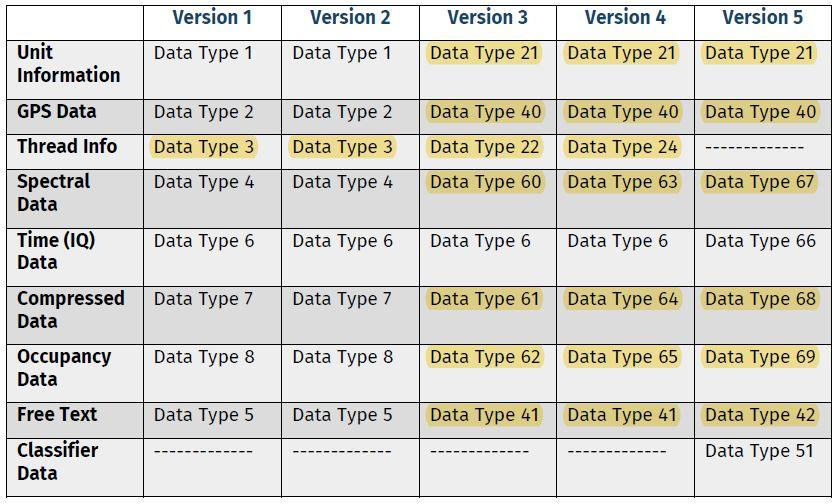

Em destaque os tipos de dados já implantados. 

**DataType 3**

function Text1 = Read_DataType3(fileID, DBH_BytesBlock)
    
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    % Data block
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));
end

**DataType 21**

function [Hostname, Text1, Text2, FileNumber] = Read_DataType21(fileID, DBH_BytesBlock)
    
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    % Data block
    Hostname      = deblank(fread(fileID, [1, 16], '*char'));
    Hostname(1:2) = upper(Hostname(1:2));
    Hostname      = erase(Hostname, '_');
    
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));  % 'CRFS default unit info  '
    Text1       = erase(Text1, '_');
    
    Text2Length = fread(fileID, 1, 'uint32');
    Text2       = deblank(fread(fileID, [1, Text2Length], '*char'));  % 'CRFS default method '
    Text2       = erase(Text2, '_');
    
    FileNumber  = fread(fileID, 1, 'uint32');
    
end

**DataType 22**

Armazena o campo descrição de cada uma das funções _peak_ e _mean_.

function Text1 = Read_DataType22(fileID, DBH_BytesBlock)
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    % Data block
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));  % {'trace mode: Clear/Write ', 'trace mode: Clear/Write, threshold: -85 dBm ', 'trace mode: MaxHold, count = 10 '}
    
end
% DataType 24
function [GroupID, Text1] = Read_DataType24(fileID, DBH_BytesBlock)
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    % Data block
    GroupID     = fread(fileID, 1, 'uint32');
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char')); % {'trace mode: Clear/Write ', 'trace mode: Clear/Write, threshold: -85 dBm ', 'trace mode: MaxHold, count = 10 '}
end

**DataType 40**

function [TimeStamp, GPS] = Read_DataType40(fileID, DBH_BytesBlock)
    
    TimeStamp = [];

    Read_CheckSum(fileID, DBH_BytesBlock);
    
    fseek(fileID, 20, 'cof');
%     % Data block
%     Date_Day   = fread(fileID, 1);
%     Date_Month = fread(fileID, 1);
%     Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
%     
%     Time_Hours   = fread(fileID, 1);
%     Time_Minutes = fread(fileID, 1);
%     Time_Seconds = fread(fileID, 1, 'uint8', 5);
%     
%     TimeStamp = datetime([Date_Year,  Date_Month,   Date_Day, ...
%                           Time_Hours, Time_Minutes, Time_Seconds]);
    
%     % GPS data
%     GPS = struct;
%     
%     Date_Day   = fread(fileID, 1);
%     Date_Month = fread(fileID, 1);
%     Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
%     
%     Time_Hours   = fread(fileID, 1);
%     Time_Minutes = fread(fileID, 1);
%     Time_Seconds = fread(fileID, 1, 'uint8', 1);
%     
%     GPS.DateTime = datetime([Date_Year,  Date_Month,   Date_Day, ...
%                              Time_Hours, Time_Minutes, Time_Seconds]);
                         
    GPS.Status     = fread(fileID, 1,  'uint8');
    GPS.Satellites = fread(fileID, 1,  'uint8');
    GPS.Heading    = fread(fileID, 1, 'uint16');
    GPS.Latitude   = fread(fileID, 1,  'int32');
    GPS.Longitude  = fread(fileID, 1,  'int32');
    GPS.Speed      = fread(fileID, 1, 'uint32');
    GPS.Altitude   = fread(fileID, 1, 'uint32');
end

**DataType 41**

function [TimeStamp, Identifier, Text1] = Read_DataType41(fileID, DBH_BytesBlock)
    
    TimeStamp = [];

    Read_CheckSum(fileID, DBH_BytesBlock);
    
    value1 = ftell(fileID);
    
    fseek(fileID, 12, 'cof');
%     % Data block
%     Date_Day   = fread(fileID, 1);
%     Date_Month = fread(fileID, 1);
%     Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
%     
%     Time_Hours   = fread(fileID, 1);
%     Time_Minutes = fread(fileID, 1);
%     Time_Seconds = fread(fileID, 1, 'uint8', 5);
%     
%     TimeStamp = datetime([Date_Year,  Date_Month,   Date_Day, ...
%                           Time_Hours, Time_Minutes, Time_Seconds]);     % Em princípio: 2 blocos
                                                
    Identifier  = deblank(fread(fileID, [1, 32], '*char'));             % 'LOGGER_NAME', 'LOGGER_VERSION'
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));    % 'log_main   ', 'build_version=1.6.7;build_date=Oct  2 2018;build_time=09:11:30;'
    
    value2 = ftell(fileID);
    value2 = value2-value1;
    if value2 < DBH_BytesBlock
        fseek(fileID, DBH_BytesBlock-value2, 'cof');
    end
    
end

**DataType 42**

function [TimeStamp, GroupID, DynamicID, Identifier, Text1] = Read_DataType42(fileID, DBH_BytesBlock)
    
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    % Data block
    value1 = ftell(fileID);
    
    Date_Day   = fread(fileID, 1);
    Date_Month = fread(fileID, 1);
    Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
    
    Time_Hours   = fread(fileID, 1);
    Time_Minutes = fread(fileID, 1);
    Time_Seconds = fread(fileID, 1, 'uint8', 5);
    
    TimeStamp = datetime([Date_Year,  Date_Month,   Date_Day, ...
                          Time_Hours, Time_Minutes, Time_Seconds]);     % Em princípio: 2 blocos
    
    GroupID   = fread(fileID, 1, 'uint32');
    DynamicID = fread(fileID, 1, 'uint32');
                                                
    Identifier  = deblank(fread(fileID, [1, 32], '*char'));                      % 'LOGGER_NAME', 'LOGGER_VERSION'
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));             % 'log_main   ', 'build_version=1.6.7;build_date=Oct  2 2018;build_time=09:11:30;'
    value2 = ftell(fileID);
    value2 = value2-value1;
    if value2 < DBH_BytesBlock
        fseek(fileID, DBH_BytesBlock-value2, 'cof');
    end
    
end

**DataType 60**

function Bin = Read_DataType60(fileID, DBH_BytesBlock, Flag)
    
    global SpecInfo
    global Index
    global CheckSum_RXE
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    if Flag
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 15);
        
        GERROR = fread(fileID, 1, 'int8', 5);
        OFFSET = fread(fileID, 1, 'int8');
        NPAD   = fread(fileID, 1);
        NTUN   = fread(fileID, 1, 'uint16');
        NAGC   = fread(fileID, 1, 'uint16', 2);
        NDATA  = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        if GERROR == -1
            TraceData = fread(fileID, [NDATA, 1], 'uint8');
            SpecInfo(Index).Data{1}(SpecInfo(Index).Samples)   = datetime([Date_Year, Date_Month, Date_Day, ...
                                                                           Time_Hours, Time_Minutes, Time_Seconds]);
            SpecInfo(Index).Data{2}(:,SpecInfo(Index).Samples) = single(TraceData)./2 + OFFSET - 127.5;
                
        else
            fseek(fileID, NDATA, 'cof');
            SpecInfo(Index).Samples = SpecInfo(Index).Samples - 1;
            CheckSum_RXE = CheckSum_RXE + 1;
            warning('\nWarning Code 1 - Global error code (radio or processing).', 'char');
        end
        
    else
        Bin = struct;
        Bin.DTYPE      = 0;
        Bin.Resolution = [];
        Bin.THRESH     = [];
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.F0 = auxF0 .* 10^expF0;
        Bin.F1 = auxF1 .* 10^expF0;
        
        Bin.AntennaID = fread(fileID, 1, 'uint8', 4);
        Bin.PROC      = fread(fileID, 1);
        Bin.NLOOP     = fread(fileID, 1, 'uint8', 1); 
        NPAD          = fread(fileID, 1);
        NTUN          = fread(fileID, 1, 'uint16');
        NAGC          = fread(fileID, 1, 'uint16', 2);
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        fseek(fileID, 4*NTUN+NAGC+Bin.NDATA, 'cof');
        
    end
    fseek(fileID, NPAD, 'cof');
    
end

**DataType 61**

function Bin = Read_DataType61(fileID, DBH_BytesBlock, Flag)
    
    global SpecInfo
    global Index
    global CheckSum_RXE
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    if Flag
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 15);
        
        GERROR = fread(fileID, 1, 'int8', 5);
        OFFSET = fread(fileID, 1, 'int8');
        NPAD   = fread(fileID, 1);
        NTUN   = fread(fileID, 1, 'uint16');
        NAGC   = fread(fileID, 1, 'uint16', 2);
        NCDATA = fread(fileID, 1, 'uint32');
        THRESH = fread(fileID, 1, 'int32');
        NDATA  = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        if GERROR == -1
            TraceData  = ones(NCDATA, 1, 'single') .* 2 .* (127.5 - OFFSET);
            ConvFactor = ((THRESH-1) - OFFSET + 127.5) .* 2;
            CompressedData = fread(fileID, [NCDATA, 1], 'uint8');
            
            ii = 0;
            jj = 0;
            while ii < length(CompressedData)
                ii=ii+1;
                TraceValue = CompressedData(ii);
                if TraceValue == 255
                    ii=ii+1;
                    kk = CompressedData(ii);
                    while kk > 0
                        jj=jj+1;
                        TraceData(jj) = ConvFactor;
                        kk = kk-1;
                    end
                elseif TraceValue == 254
                    ii=ii+1;
                    jj=jj+1;
                    TraceData(jj) = CompressedData(ii);
                else
                    jj=jj+1;
                    TraceData(jj) = TraceValue;
                end
            end
            TraceData(length(TraceData)+1:NDATA) = ConvFactor;
            SpecInfo(Index).Data{1}(SpecInfo(Index).Samples)   = datetime([Date_Year, Date_Month, Date_Day, ...
                                                                           Time_Hours, Time_Minutes, Time_Seconds]);
            SpecInfo(Index).Data{2}(:,SpecInfo(Index).Samples) = single(TraceData)./2 + OFFSET - 127.5;
                
        else
            fseek(fileID, NCDATA, 'cof');
            SpecInfo(Index).Samples = SpecInfo(Index).Samples - 1;
            CheckSum_RXE = CheckSum_RXE + 1;
            warning('\nWarning Code 1 - Global error code (radio or processing).', 'char');
        end
        
    else
        Bin = struct;
        Bin.DTYPE      = 0;
        Bin.Resolution = [];
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.F0 = auxF0 .* 10^expF0;
        Bin.F1 = auxF1 .* 10^expF0;
        
        Bin.AntennaID = fread(fileID, 1, 'uint8', 4);
        Bin.PROC      = fread(fileID, 1);
        Bin.NLOOP     = fread(fileID, 1, 'uint8', 1); 
        NPAD          = fread(fileID, 1);
        NTUN          = fread(fileID, 1, 'uint16');
        NAGC          = fread(fileID, 1, 'uint16', 2);
        NCDATA        = fread(fileID, 1, 'uint32');
        Bin.THRESH    = fread(fileID, 1, 'int32');
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        fseek(fileID, 4*NTUN+NAGC+NCDATA, 'cof');
        
    end
    fseek(fileID, NPAD, 'cof');
    
end

**DataType 62**

function Bin = Read_DataType62(fileID, DBH_BytesBlock, Flag)
    
    global SpecInfo
    global Index
    global CheckSum_RXE
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    if Flag
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 15);
        
        GERROR = fread(fileID, 1, 'int8', 13);
        NPAD   = fread(fileID, 1, 'uint8', 3);
        NDATA  = fread(fileID, 1, 'uint32');
    
        if GERROR == -1
            TraceData = fread(fileID, [NDATA, 1], 'uint8');
            
            SpecInfo(Index).Data{1}(SpecInfo(Index).Samples)   = datetime([Date_Year, Date_Month, Date_Day, ...
                                                                           Time_Hours, Time_Minutes, Time_Seconds]);
            SpecInfo(Index).Data{2}(:,SpecInfo(Index).Samples) = single(TraceData)./2;
        else
            fseek(fileID, NDATA, 'cof');
            SpecInfo(Index).Samples = SpecInfo(Index).Samples - 1;
            CheckSum_RXE = CheckSum_RXE + 1;
            warning('\nWarning Code 1 - Global error code (radio or processing).', 'char');
        end
        
    else
        Bin = struct;
        Bin.PROC       = 0;
        Bin.DTYPE      = 0;
        Bin.Resolution = [];
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.F0 = auxF0 .* 10^expF0;
        Bin.F1 = auxF1 .* 10^expF0;
        
        Bin.AntennaID = fread(fileID, 1, 'uint8', 4);
        Bin.THRESH    = fread(fileID, 1, 'int16', 8);
        NPAD          = fread(fileID, 1, 'uint8', 3);
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        fseek(fileID, Bin.NDATA, 'cof');
        
    end
    fseek(fileID, NPAD, 'cof');
    
end

**DataType 63**

function Bin = Read_DataType63(fileID, DBH_BytesBlock, Flag)
    
    global SpecInfo
    global Index
    global CheckSum_RXE
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    if Flag
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 32);
        
        OFFSET = fread(fileID, 1, 'int8');
        GERROR = fread(fileID, 1, 'int8', 2);
        NTUN   = fread(fileID, 1, 'uint16');
        NAGC   = fread(fileID, 1, 'uint16');
        NPAD   = fread(fileID, 1);
        NDATA  = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        if GERROR == -1
            TraceData = fread(fileID, [NDATA, 1], 'uint8');
            SpecInfo(Index).Data{1}(SpecInfo(Index).Samples)   = datetime([Date_Year, Date_Month, Date_Day, ...
                                                                           Time_Hours, Time_Minutes, Time_Seconds]);
            SpecInfo(Index).Data{2}(:,SpecInfo(Index).Samples) = single(TraceData)./2 + OFFSET - 127.5;
                
        else
            fseek(fileID, NDATA, 'cof');
            SpecInfo(Index).Samples = SpecInfo(Index).Samples - 1;
            CheckSum_RXE = CheckSum_RXE + 1;
            warning('\nWarning Code 1 - Global error code (radio or processing).', 'char');
        end
    else
        Bin = struct;
        Bin.Resolution = [];
        Bin.THRESH     = [];
      
        fseek(fileID, 12, 'cof');
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32', 8);
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        Bin.NLOOP     = fread(fileID, 1, 'uint32');
        Bin.AntennaID = fread(fileID, 1);
        Bin.PROC      = fread(fileID, 1);
        Bin.DTYPE     = fread(fileID, 1, 'uint8', 4);
        NTUN          = fread(fileID, 1, 'uint16');
        NAGC          = fread(fileID, 1, 'uint16');
        NPAD          = fread(fileID, 1);
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        fseek(fileID, 4*NTUN+NAGC+Bin.NDATA, 'cof');
    end
    fseek(fileID, NPAD, 'cof');
    
end

**DataType 64**

function Bin = Read_DataType64(fileID, DBH_BytesBlock, Flag)
    
    global SpecInfo
    global Index
    global CheckSum_RXE
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    if Flag
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 32);
        
        OFFSET = fread(fileID, 1, 'int8');
        GERROR = fread(fileID, 1, 'int8', 2);
        NTUN   = fread(fileID, 1, 'uint16');
        NAGC   = fread(fileID, 1, 'uint16');
        NPAD   = fread(fileID, 1);
        NCDATA = fread(fileID, 1, 'uint32');
        THRESH = fread(fileID, 1, 'int32');
        NDATA  = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        if GERROR == -1
            TraceData  = ones(NCDATA, 1, 'single') .* 2 .* (127.5 - OFFSET);
            ConvFactor = ((THRESH-1) - OFFSET + 127.5) .* 2;
            CompressedData = fread(fileID, [NCDATA, 1], 'uint8');
            ii = 0;
            jj = 0;
            while ii < length(CompressedData)
                ii=ii+1;
                TraceValue = CompressedData(ii);
                if TraceValue == 255
                    ii=ii+1;
                    kk = CompressedData(ii);
                    while kk > 0
                        jj=jj+1;
                        TraceData(jj) = ConvFactor;
                        kk = kk-1;
                    end
                elseif TraceValue == 254
                    ii=ii+1;
                    jj=jj+1;
                    TraceData(jj) = CompressedData(ii);
                else
                    jj=jj+1;
                    TraceData(jj) = TraceValue;
                end
            end
            TraceData(length(TraceData)+1:NDATA) = ConvFactor;
            
            SpecInfo(Index).Data{1}(SpecInfo(Index).Samples)   = datetime([Date_Year, Date_Month, Date_Day, ...
                                                                           Time_Hours, Time_Minutes, Time_Seconds]);
            SpecInfo(Index).Data{2}(:,SpecInfo(Index).Samples) = single(TraceData)./2 + OFFSET - 127.5;
             
        else
            fseek(fileID, NCDATA, 'cof');
            SpecInfo(Index).Samples = SpecInfo(Index).Samples - 1;
            CheckSum_RXE = CheckSum_RXE + 1;
            warning('\nWarning Code 1 - Global error code (radio or processing).', 'char');
        end
        
    else
        Bin = struct;
        Bin.Resolution = [];
        
        fseek(fileID, 12, 'cof');
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32', 8);
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        Bin.NLOOP     = fread(fileID, 1, 'uint32');
        Bin.AntennaID = fread(fileID, 1);
        Bin.PROC      = fread(fileID, 1);
        Bin.DTYPE     = fread(fileID, 1, 'uint8', 4);
        NTUN          = fread(fileID, 1, 'uint16');
        NAGC          = fread(fileID, 1, 'uint16');
        NPAD          = fread(fileID, 1, 'uint8');
        NCDATA        = fread(fileID, 1, 'uint32');
        Bin.THRESH    = fread(fileID, 1, 'int32');
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        fseek(fileID, 4*NTUN+NAGC+NCDATA, 'cof');
    end
    fseek(fileID, NPAD, 'cof');
    
end

**DataType 65**

function Bin = Read_DataType65(fileID, DBH_BytesBlock, Flag)
    
    global SpecInfo
    global Index
    global CheckSum_RXE
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    if Flag
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 29);
        
        GERROR    = fread(fileID, 1, 'int8', 2);
        NPAD      = fread(fileID, 1, 'uint8', 4);
        Bin.NDATA = fread(fileID, 1, 'uint32');
        
        if GERROR == -1
            TraceData = fread(fileID, [Bin.NDATA, 1], 'uint8');
            
            SpecInfo(Index).Data{1}(SpecInfo(Index).Samples)   = datetime([Date_Year, Date_Month, Date_Day, ...
                                                                           Time_Hours, Time_Minutes, Time_Seconds]);
            SpecInfo(Index).Data{2}(:,SpecInfo(Index).Samples) = single(TraceData)./2;
            
        else
            fseek(fileID, Bin.NDATA, 'cof');
            SpecInfo(Index).Samples = SpecInfo(Index).Samples - 1;
            CheckSum_RXE = CheckSum_RXE + 1;
            warning('\nWarning Code 1 - Global error code (radio or processing).', 'char');
        end
        
    else
        Bin = struct;
        Bin.Resolution = [];
        
        fseek(fileID, 12, 'cof');
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32', 4);
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        Bin.NLOOP     = fread(fileID, 1, 'uint32');
        Bin.AntennaID = fread(fileID, 1);
        Bin.PROC      = fread(fileID, 1);
        Bin.DTYPE     = fread(fileID, 1, 'uint16', 3);
        NPAD          = fread(fileID, 1);     
        Bin.THRESH    = fread(fileID, 1, 'int16', 2);
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        fseek(fileID, Bin.NDATA, 'cof');
    end
    fseek(fileID, NPAD, 'cof');
    
end

**DataType 67**

function Bin = Read_DataType67(fileID, DBH_BytesBlock, Flag)
    
    global SpecInfo
    global Index
    global CheckSum_RXE
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    if Flag
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 13);
        
        TextLength = fread(fileID, 1, 'uint32');
        fseek(fileID,TextLength+31,'cof');
        
        OFFSET     = fread(fileID, 1, 'int8');
        GERROR     = fread(fileID, 1, 'int8', 2);
        NTUN       = fread(fileID, 1, 'uint16');
        NAGC       = fread(fileID, 1, 'uint16');
        NPAD       = fread(fileID, 1);
        NDATA      = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        if GERROR == -1
            TraceData = fread(fileID, [NDATA, 1], 'uint8');
            
            SpecInfo(Index).Data{1}(SpecInfo(Index).Samples)   = datetime([Date_Year, Date_Month, Date_Day, ...
                                                                           Time_Hours, Time_Minutes, Time_Seconds]);
            SpecInfo(Index).Data{2}(:,SpecInfo(Index).Samples) = single(TraceData)./2 + OFFSET - 127.5;
                
        else
            fseek(fileID, NDATA, 'cof');
            SpecInfo(Index).Samples = SpecInfo(Index).Samples - 1;
            CheckSum_RXE = CheckSum_RXE + 1;
            warning('\nWarning Code 1 - Global error code (radio or processing).', 'char');
        end
        
    else
        Bin = struct;
        Bin.THRESH = [];
        
        fseek(fileID, 20, 'cof');
        TextLength = fread(fileID, 1, 'uint32');
        Bin.Text   = deblank(fread(fileID, [1, TextLength], '*char'));
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1,  'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1,  'int32');
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        Bin.Resolution = fread(fileID, 1, 'uint32', 8);
        Bin.NLOOP      = fread(fileID, 1, 'uint32');
        Bin.AntennaID  = fread(fileID, 1);
        Bin.PROC       = fread(fileID, 1);
        Bin.DTYPE      = fread(fileID, 1, 'uint8', 4);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16');
        NPAD           = fread(fileID, 1);
        Bin.NDATA      = fread(fileID, 1, 'uint32');
        fseek(fileID, 4*NTUN+NAGC+Bin.NDATA, 'cof');
    end
    fseek(fileID, NPAD, 'cof');
    
end

**DataType 68**

function Bin = Read_DataType68(fileID, DBH_BytesBlock, Flag)
    
    global SpecInfo
    global Index
    global CheckSum_RXE
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    if Flag
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 13);
        
        TextLength = fread(fileID, 1, 'uint32');
        fseek(fileID,TextLength+31,'cof');
        
        OFFSET = fread(fileID, 1, 'int8');
        GERROR = fread(fileID, 1, 'int8', 2);
        NTUN   = fread(fileID, 1, 'uint16');
        NAGC   = fread(fileID, 1, 'uint16');
        NPAD   = fread(fileID, 1);
        NCDATA = fread(fileID, 1, 'uint32');
        THRESH = fread(fileID, 1, 'int32');
        NDATA  = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        if GERROR == -1
            TraceData  = ones(NCDATA, 1, 'single') .* 2 .* (127.5 - OFFSET);
            ConvFactor = ((THRESH-1) - OFFSET + 127.5) .* 2;
            CompressedData = fread(fileID, [NCDATA, 1], 'uint8');
            ii = 0;
            jj = 0;
            while ii < length(CompressedData)
                ii=ii+1;
                TraceValue = CompressedData(ii);
                if TraceValue == 255
                    ii=ii+1;
                    kk = CompressedData(ii);
                    while kk > 0
                        jj=jj+1;
                        TraceData(jj) = ConvFactor;
                        kk = kk-1;
                    end
                elseif TraceValue == 254
                    ii=ii+1;
                    jj=jj+1;
                    TraceData(jj) = CompressedData(ii);
                else
                    jj=jj+1;
                    TraceData(jj) = TraceValue;
                end
            end
            TraceData(length(TraceData)+1:NDATA) = ConvFactor;
            
            SpecInfo(Index).Data{1}(SpecInfo(Index).Samples)   = datetime([Date_Year, Date_Month, Date_Day, ...
                                                                           Time_Hours, Time_Minutes, Time_Seconds]);
            SpecInfo(Index).Data{2}(:,SpecInfo(Index).Samples) = single(TraceData)./2 + OFFSET - 127.5;
            
        else
            fseek(fileID, NCDATA, 'cof');
            SpecInfo(Index).Samples = SpecInfo(Index).Samples - 1;
            CheckSum_RXE = CheckSum_RXE + 1;
            warning('\nWarning Code 1 - Global error code (radio or processing).', 'char');
        end
        
    else
        Bin = struct;
        
        fseek(fileID, 20, 'cof');
        TextLength = fread(fileID, 1, 'uint32');
        Bin.Text   = deblank(fread(fileID, [1, TextLength], '*char'));
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1,  'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1,  'int32');
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        Bin.Resolution = fread(fileID, 1, 'uint32', 8);
        Bin.NLOOP      = fread(fileID, 1, 'uint32');
        Bin.AntennaID  = fread(fileID, 1);
        Bin.PROC       = fread(fileID, 1);
        Bin.DTYPE      = fread(fileID, 1, 'uint8', 4);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16');
        NPAD           = fread(fileID, 1);                                  % Number of bytes of padding (0, 1, 2 or 3)
        NCDATA         = fread(fileID, 1, 'uint32');
        Bin.THRESH     = fread(fileID, 1, 'int32');
        Bin.NDATA      = fread(fileID, 1, 'uint32');
        fseek(fileID, 4*NTUN+NAGC+NCDATA, 'cof');
        
    end
    fseek(fileID, NPAD, 'cof');
    
end

**DataType 69**

function Bin = Read_DataType69(fileID, DBH_BytesBlock, Flag)
    
    global SpecInfo
    global Index
    global CheckSum_RXE
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    if Flag
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 13);
        
        TextLength = fread(fileID, 1, 'uint32');
        fseek(fileID,TextLength+28,'cof');
        GERROR     = fread(fileID, 1,  'int8', 2);
        NPAD       = fread(fileID, 1, 'uint8', 4);      
        NDATA      = fread(fileID, 1, 'uint32');
        
        if GERROR == -1
            TraceData = fread(fileID, [NDATA, 1], 'uint8');
            
            SpecInfo(Index).Data{1}(SpecInfo(Index).Samples)   = datetime([Date_Year, Date_Month, Date_Day, ...
                                                                           Time_Hours, Time_Minutes, Time_Seconds]);
            SpecInfo(Index).Data{2}(:,SpecInfo(Index).Samples) = single(TraceData)./2;
            
        else
            fseek(fileID, NDATA, 'cof');
            SpecInfo(Index).Samples = SpecInfo(Index).Samples - 1;
            CheckSum_RXE = CheckSum_RXE + 1;
            warning('\nWarning Code 1 - Global error code (radio or processing).', 'char');
        end
        
    else
        Bin = struct;
        
        fseek(fileID, 20, 'cof');
      
        TextLength = fread(fileID, 1, 'uint32');
        Bin.Text   = deblank(fread(fileID, [1, TextLength], '*char'));
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1,  'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1,  'int32');
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        Bin.Resolution = fread(fileID, 1, 'uint32', 4);
        Bin.NLOOP      = fread(fileID, 1, 'uint32');
        Bin.AntennaID  = fread(fileID, 1);
        Bin.PROC       = fread(fileID, 1);
        Bin.DTYPE      = fread(fileID, 1, 'uint16', 3);
        NPAD           = fread(fileID, 1);      
        Bin.THRESH     = fread(fileID, 1, 'int16', 2);
        Bin.NDATA      = fread(fileID, 1, 'uint32');
        fseek(fileID, Bin.NDATA, 'cof');
        
    end
    fseek(fileID, NPAD, 'cof');
    
end